addpath('./functions');
addpath('./data');

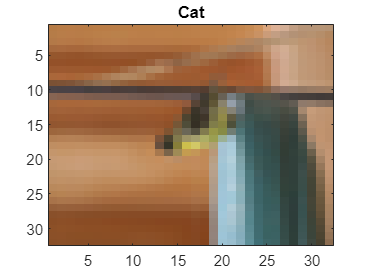

load('data\cifar-10-batches-mat\data_batch_1.mat')

N = size(data, 1);
data = data';
data = reshape(data, [32,32,3,N]);
labels = categorical(labels);
labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = [0, ...
                  1, ...
                  2, ...
                  3, ...
                  4, ...
                  5, ...
                  6, ...
                  7, ...
                  8, ...
                  9, ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(N);

imagesc(data(:,:,:,idx))
title(label2name(labels(idx)))